# kgme - single fish

## load data structure

IN LAB

%load("/Volumes/Elements/kg.mat");
load("/Users/eric/Documents/MATLAB/kgtest2.mat");
addpath('/Users/eric/SparkleShare/github.com/FishCodeGH/Gallman/');

AT HOME

load("/Volumes/Elements/kg.mat");
%load("/Users/kathryngallman/Documents/MATLAB/kgbackup.mat");
addpath("/Users/kathryngallman/SparkleShare/github.com/FishCodeGH/Gallman");

## save data structure

IN LAB

save("/Users/eric/Documents/MATLAB/kgtest2.mat", "kg", '-v7.3');
save("/Volumes/Elements/kg.mat", 'kg', '-v7.3');
% save("/Volumes/My Book/Gallman/kg.mat", 'kg');


AT HOME

save("/Users/kathryngallman/Documents/MATLAB/kgbackup.mat", "kg");
save("/Volumes/Elements/kg.mat", 'kg');

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/Elements/Gallman/1212LD/Frank12Dlpulse-April-18-2022-D/");
k = 138;

k = 1,2;           4:4 LD

k = 3-5;           48:48 LD 

k = 6, 7;          10:10 LD

k = 8, 9           6:6 LD

      k = 9 - time shifty

k = 10, 11;       24:24 LD

k = 12-17;       12:12 LD

    k=13 - two different fish - need to separate! - poweridx for second fish - none for first fish cause it was dying

    k = 15 very short and shitty

k = 17 two different fish - need to separate!

k = 18-20         5:5 LD

    k = 18 - shit data. replaced Eigen05-Nov-8-2020-A with new poweridx from k = 19;

    k = 20 - just weird. don't use light timers they shift

k = 21 - Eugene 

k = 22   Eugene 12:12 LD - wrong folder label - from super old data - spring 2020 Eigen

k = 23 - Milo

k = 24 - fish run - not sure which fish - need to check

k = 25-27         8:8 LD

k = 28-31        13:13 LD

    k = 28 - same as k = 31 but trimmed

    k = 29 - don't use. data is backwards

    k = 30 - if trimmed and then outlier removed could salvage data - needs multiple power idxs

    k = 31 - needs second poweridx for channel 1 data - not sure about numberings yet

k = 32-34        6:6 LD

    social tubes - data trimmed - maybe rerun with new numbers for switches

    k = 34 - weird data. backwards

k = 35, 36       8:8 LD

k = 37-40        20:20 LD

    k = 39 - salvagable, needs to be trimmed and outliered.  

k = 41-43        16:16 LD - kinda shitty tbh

k = 44, 45         48:48 LD

    k = 45         just not good

k = 47,48        12:12 - Confused as to why there are two folders

k = 49               48:48 LD

k = 50-53         XX temp exp (code 99 for ld)

k = 54, 55        4:4 LD

    k = 54 ch 1 only

    k = 55 ch 2 only

k = 56, 57        24:24 LD - some problems with electrodes

k = 58, 59        5:5 LD

    k = 59 outlier fish - super huge amplitude oscillations

k = 60, 61        10:10 LD

    k = 61 outlier fish " "

k = 63               12:12 to 17 to 24... no idea...

k = 64-67        12:12 - 4:4 - 12:12 - 4:4 - 12:12 LD phase exp.

k = 68-71         124 LD same as 64-67 but take 2         

k = 72- 75        124 take 3 (thanksgiving)

                      k = 73, 75 - fish died halfway through

k = 76-79                24:24 LD

                        k = 79 needs to be dec data from rig D - need to recopy over from VitaminI

k = 80-83            48:48

k = 84,85            12:12

k = 86-89       10:10 LD

                            k = 87 electrode bumping

k = 90-93            20:20 LD

                        k = 93, 90 temp variation

k = 94            13:13 LD; k = 31  

k = 95            10:10 LD; k = 60 different poweridx

k = 96            5:5 LD; k = 58 different poweridx for ch2 data 

k = 97            48:48 LD

k = 98            12:12 LD  

k = 99            6:6 LD; k = 9 - different poweridx (first bit)  

k = 100  k = 17 (need to split) - power idx for 1st  fish

k = 101         k = 13 -second fish

k = 102        48:48 LD - heater broke - fish died - RIP Cheshire

k = 103        48:48LDtemp  - use for temp modulation analysis

k = 104         48:48LDtemp - Greenie

k = 105         48:48LDtemp - Lydia

k = 106         48:48 LD -Pablo

k = 107          48:48 LD -Rose 

k = 108        LLtemp - Ginumbo

k = 109        LLtemp-Mika - only use channel 2

k = 110        LL only - Picasso - only one good channel

k = 111    kg(1) untrimmed

k = 112        12:12LD to LL -  Rose

k = 113        12Ldpulse (11:1LD) - Ginumbo

k = 114        12Ldpulse (11:1 LD) - Mika

k = 115        12Ldpulse (11:1 LD) - Picasso - ch2 only

k = 116        12:12; k = 98 with gain adjustment; ch1/20 ch2/10

k = 117        5:5; k = 58 with gain adjustment; ch1/4

k = 118        12:12; k = 47 with gain adjustment; ch2/30

k = 119        24:24; k = 56 with gain adjustment; ch1/4

k = 120        24:24; k = 76 with gain adjustment

k = 121        6Ldpulse (5:1LD) - Ginumbo

k = 122        kg(124) - just in case i fuck something up

k = 123        6Ldpulse (5:1LD) - Mika

k = 124        6Ldpulse (5:1LD) - Picasso - not many triggers - luz needs work - fish died

k = 125        6Ldpulse (5:1LD) - Rose

k = 126        6Dlpuse (1:5 LD) - Rein

k = 127        6Dlpulse (1:5 LD) - Mika Rig E

k = 128        6Dlpulse (1:5 LD - Rose

k = 129        13:13 LD Rose

k = 130        13:13 LD - EODsignal - Ginumbo

k = 131        13:13 LD - Mika - Rig A

k = 132        13:13 LD - Mika - Rig E

k = 133        13:13 LD - Mika - Rig A vs Rig E

k = 134        13:13 - EODsignal-Ginumbo (same as 130 plus new signal analysis code)

k = 135        5:5 LD - Mika

k = 136        5:5 LD - EOD signal - Rein

k = 137        5:5 LD - Rose

k = 138        12Dlpulse (1:11 LD) - Frank

## generate amplitude data

kg(k).e = KatieAssembler('Eigen*', 40000, 23);
%kg(k).e = KatieAssembler('Eigen*', 20000, 22); %really old data
%kg(k).e = KatieAssembler('Eigen*', 40000, 24); %Katie is bad at typing...

kg(k).e = KatieAssemblerSig('Eigen*', 40000, 23, 300);

## initial plotter

ans = 2.0681

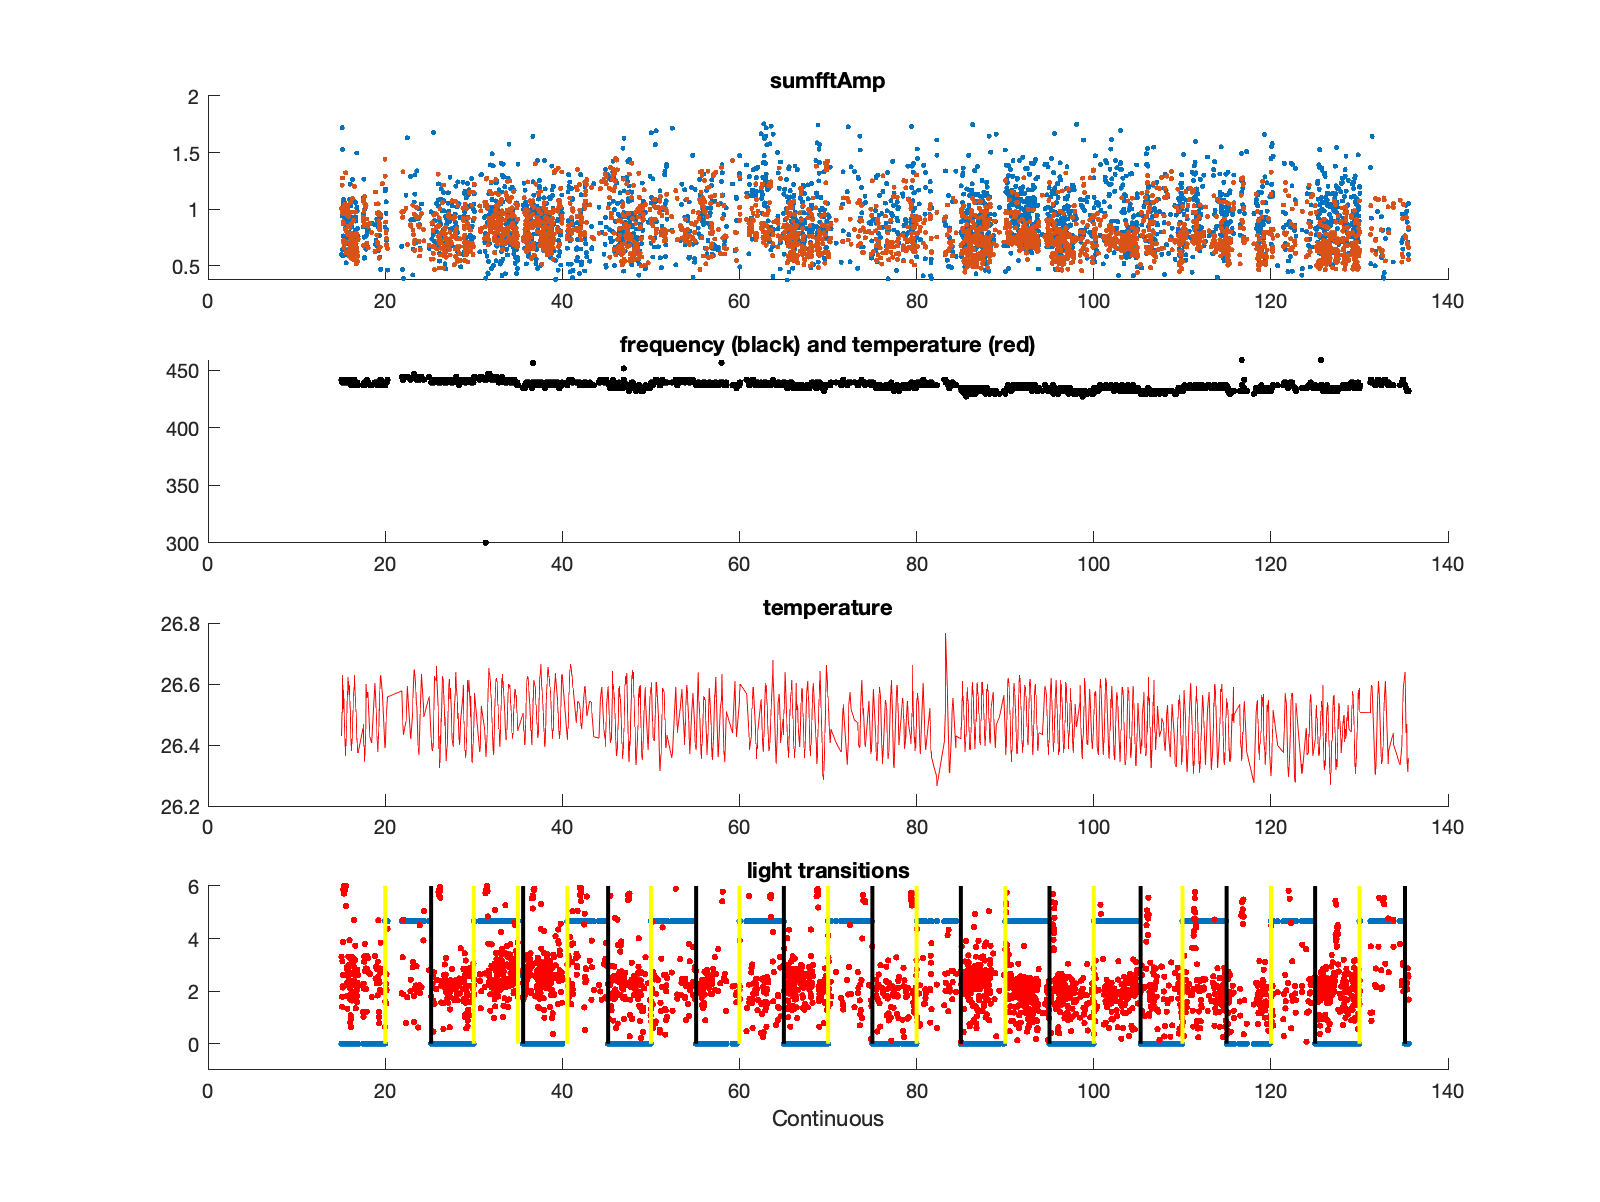

k_initialplotter(kg(k));

## edits

#### trim data

extra step in case of instant clicking regret...

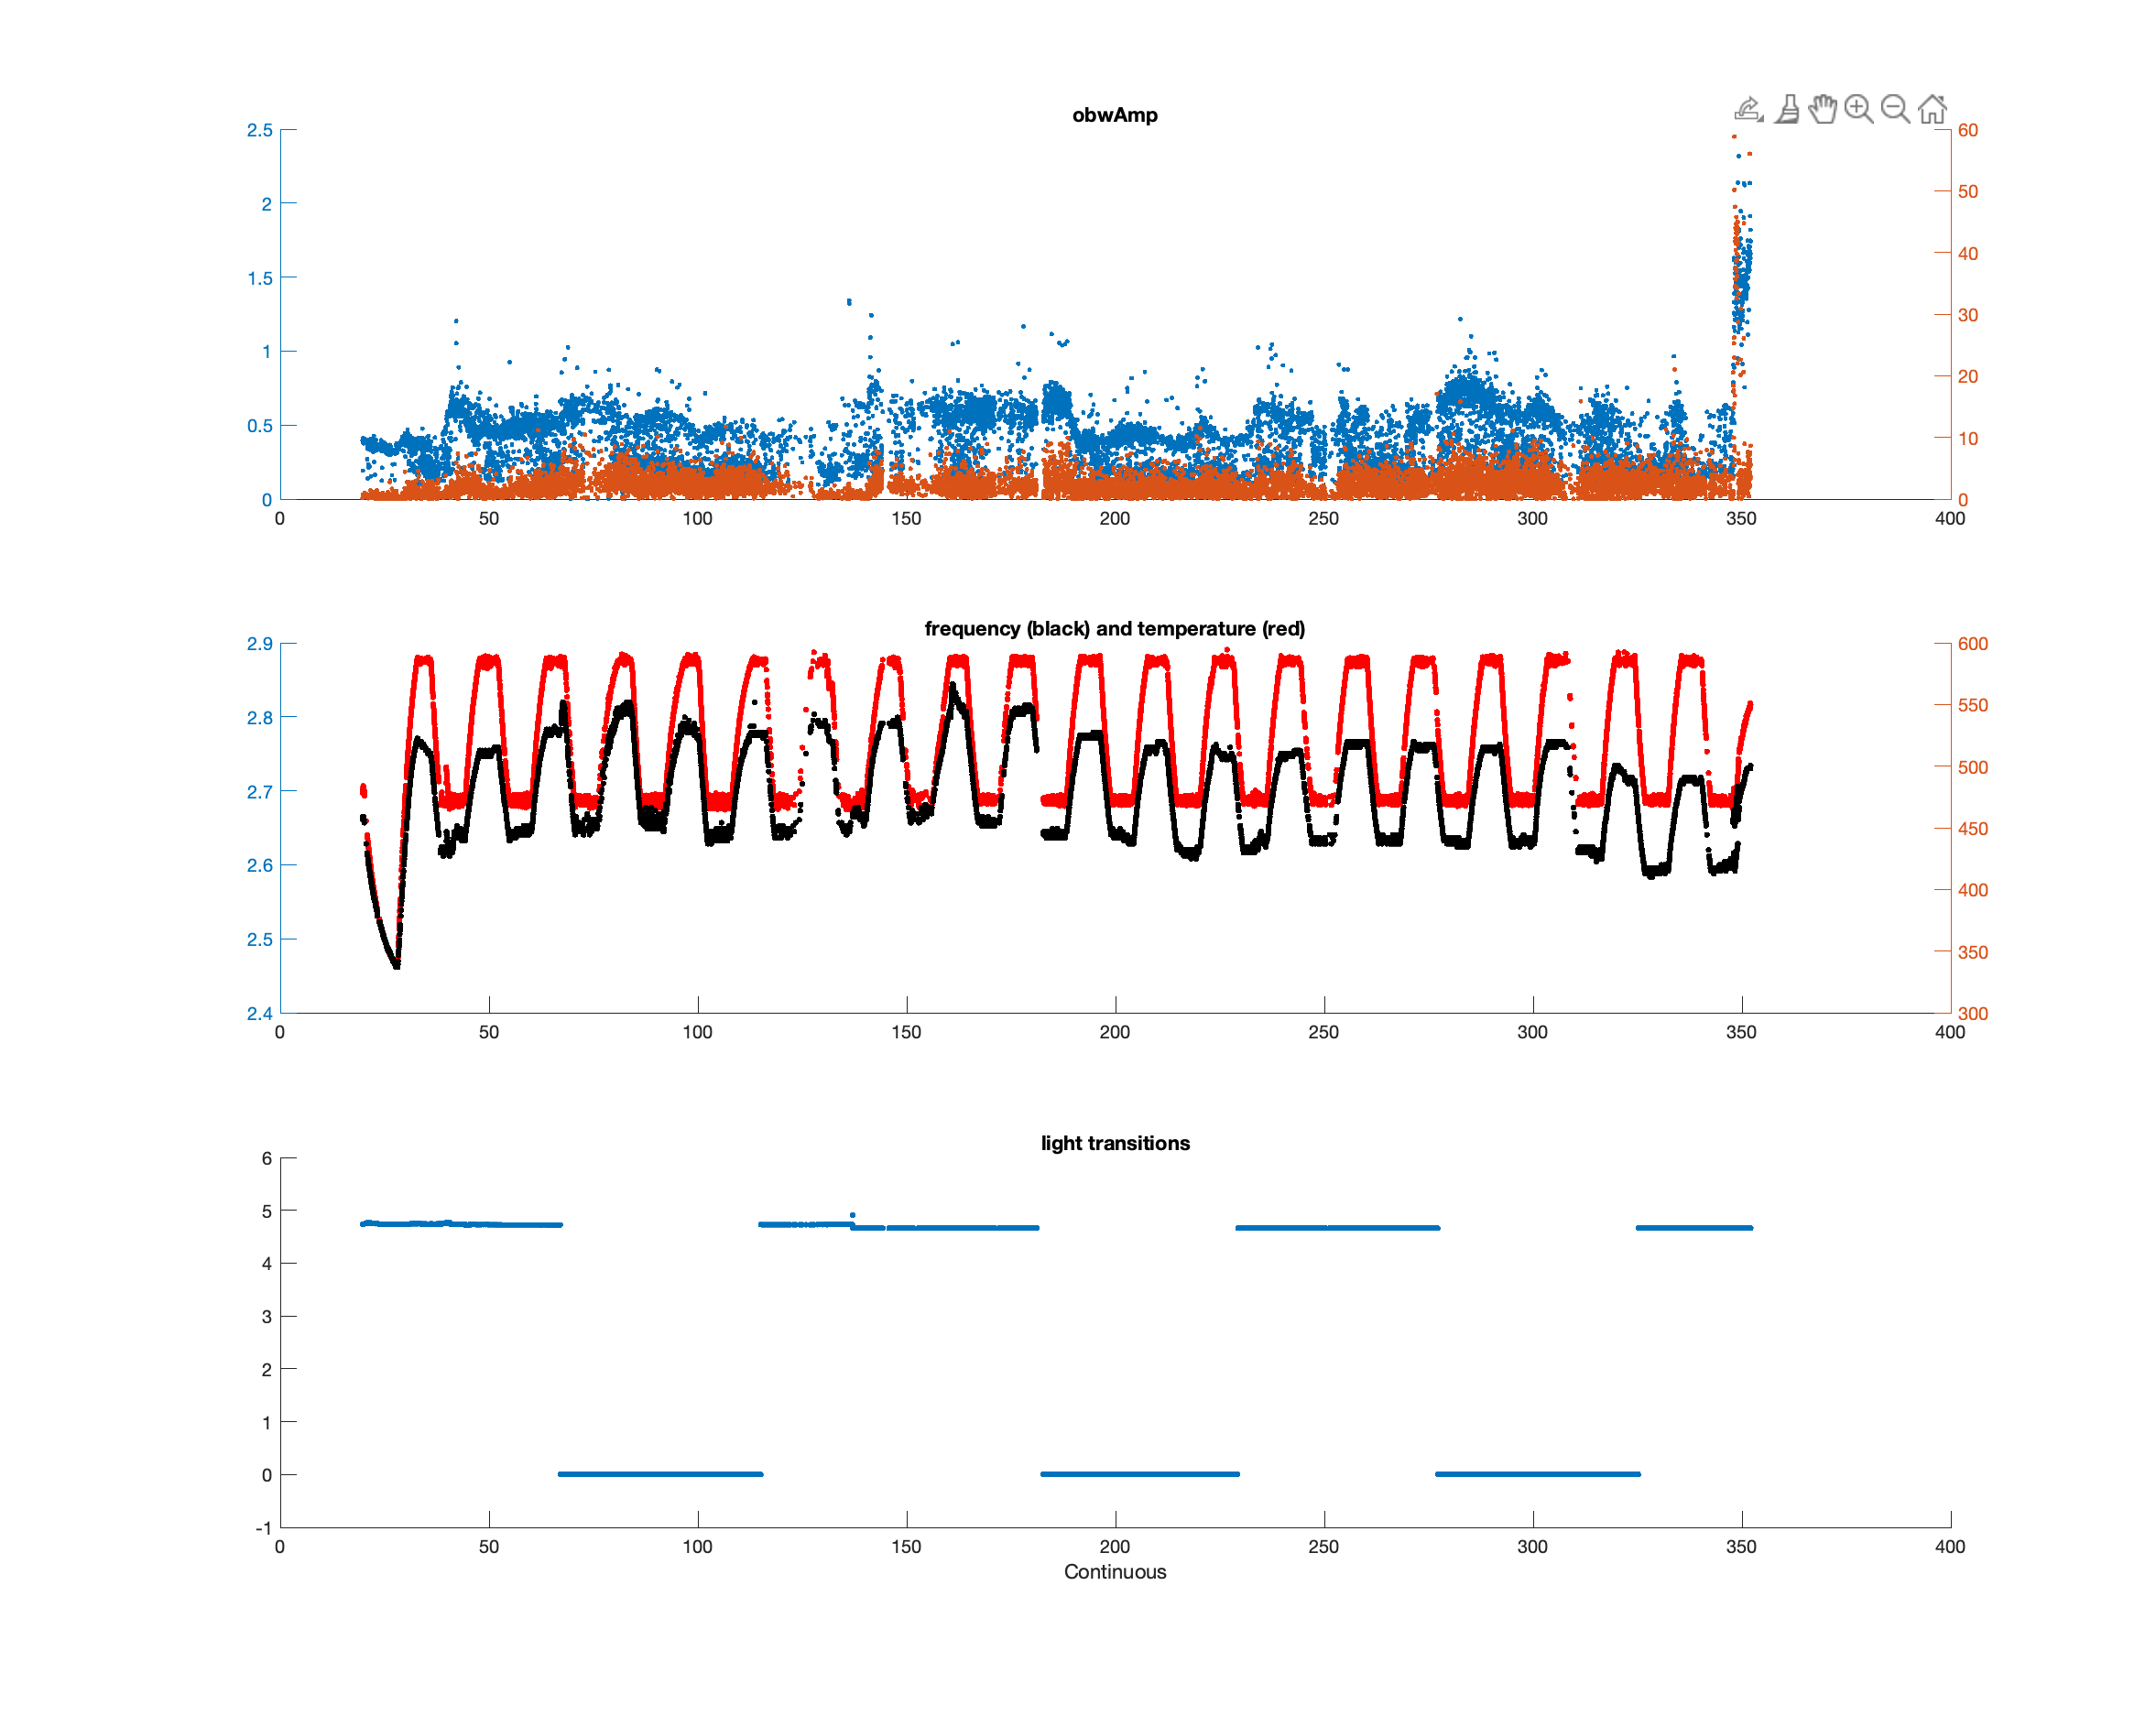

tempdata = KatieTrimmer(kg(k).e);

if before was on purpose 

kg(k).e = tempdata;

#### Remove outliers

Must be redone after trimming

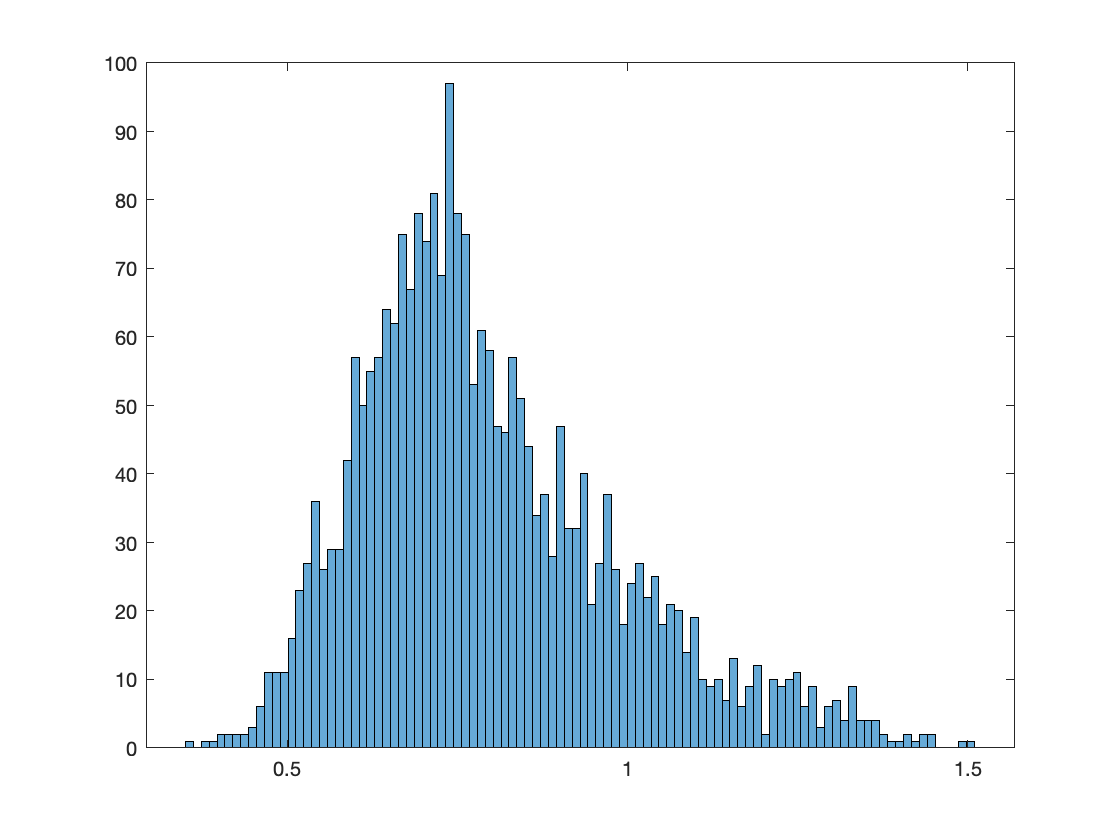

kg(k).idx = KatieRemover(kg(k).e);

## Label

#### light experiment

manual entry into command line - click in window 

kg(k).info = KatieLabeler(kg(k).e);

#### temperature experiment

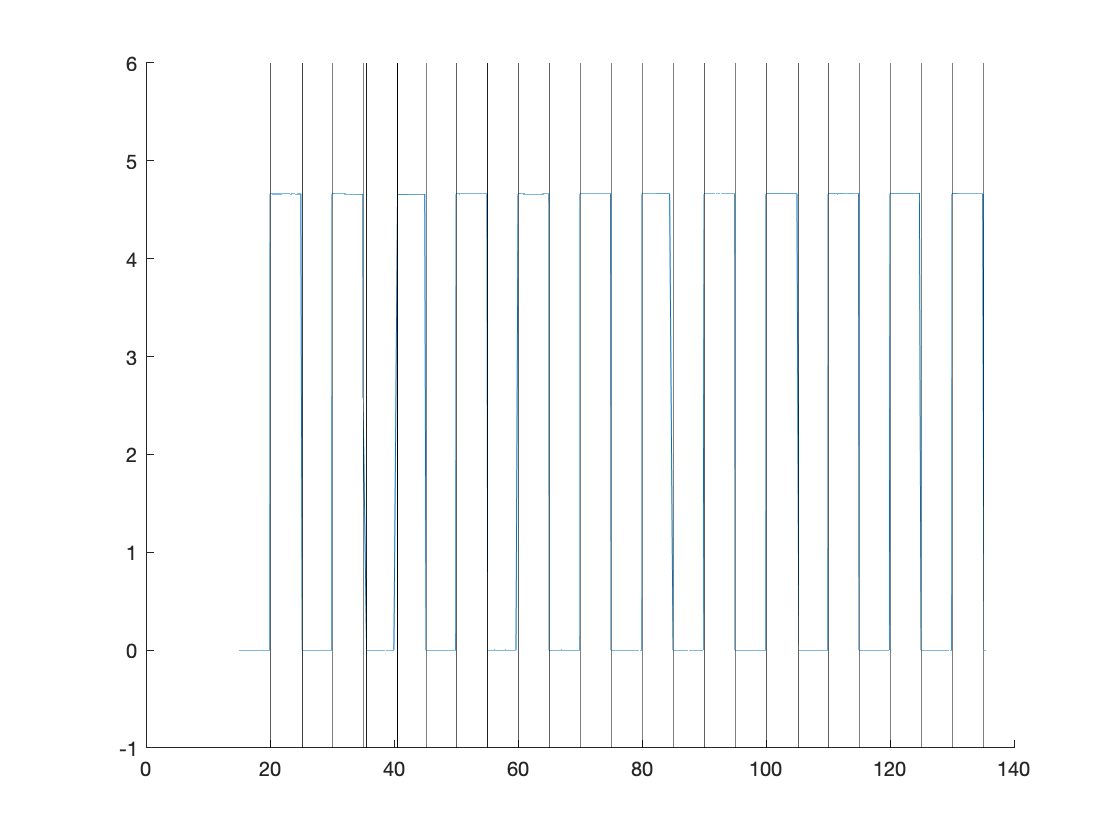

kg(k).info = KatieTempLabeler(kg(k).e);

## initial spline plotter

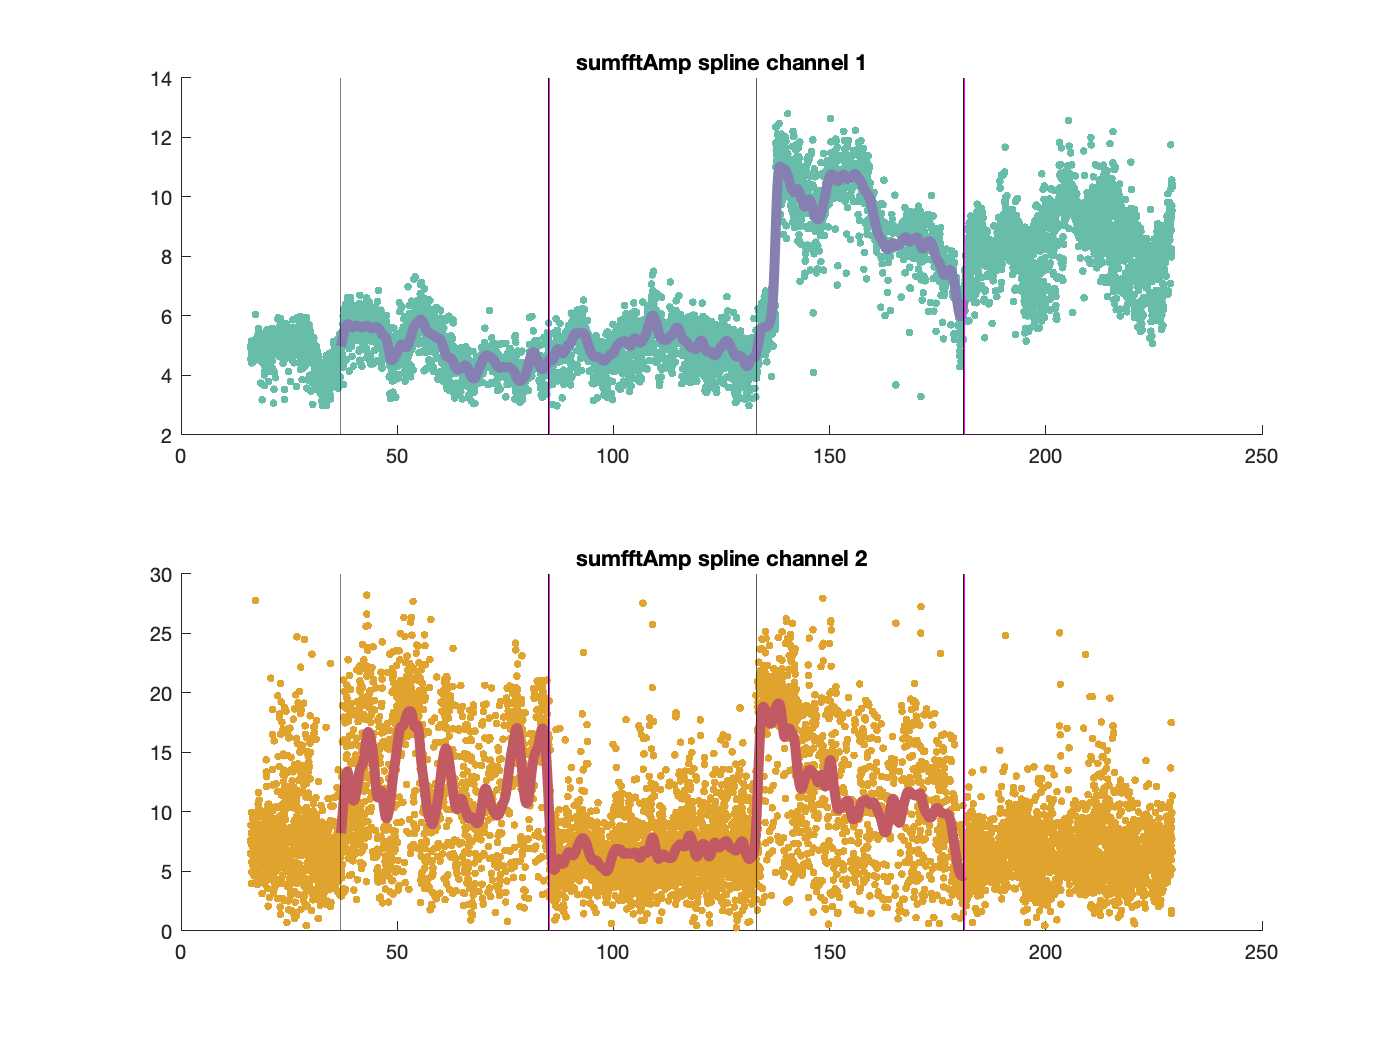

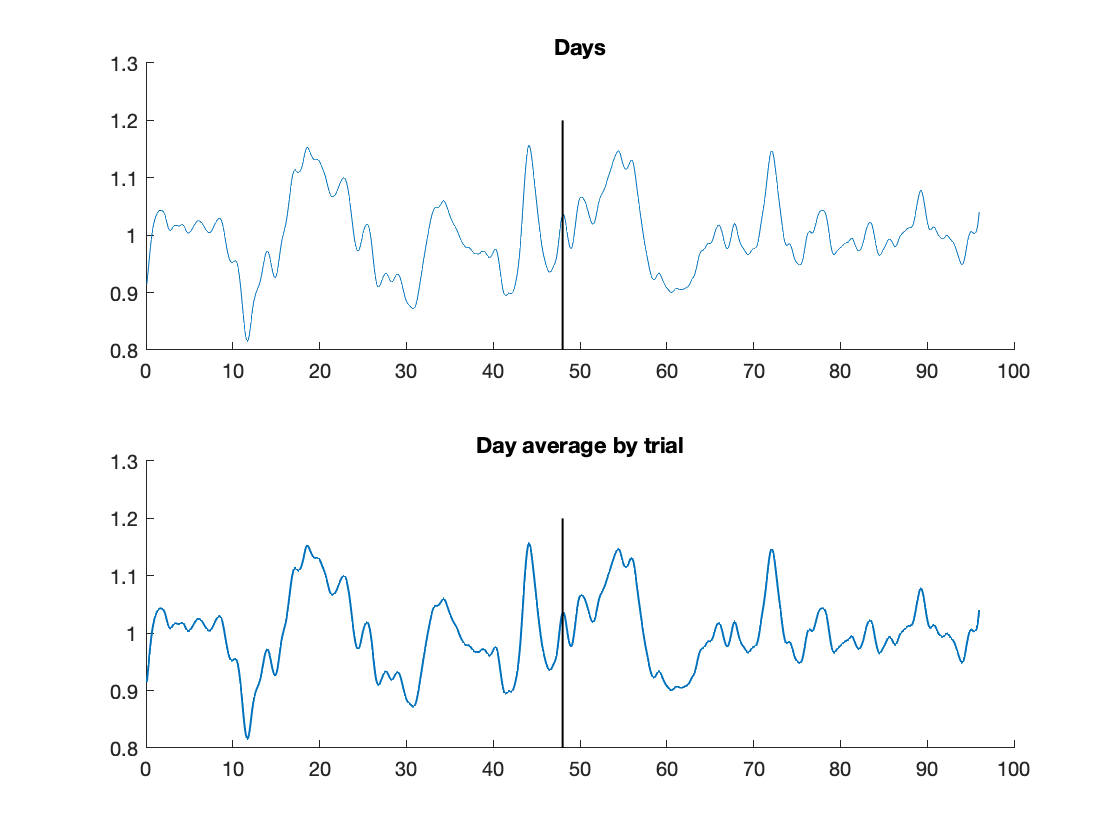

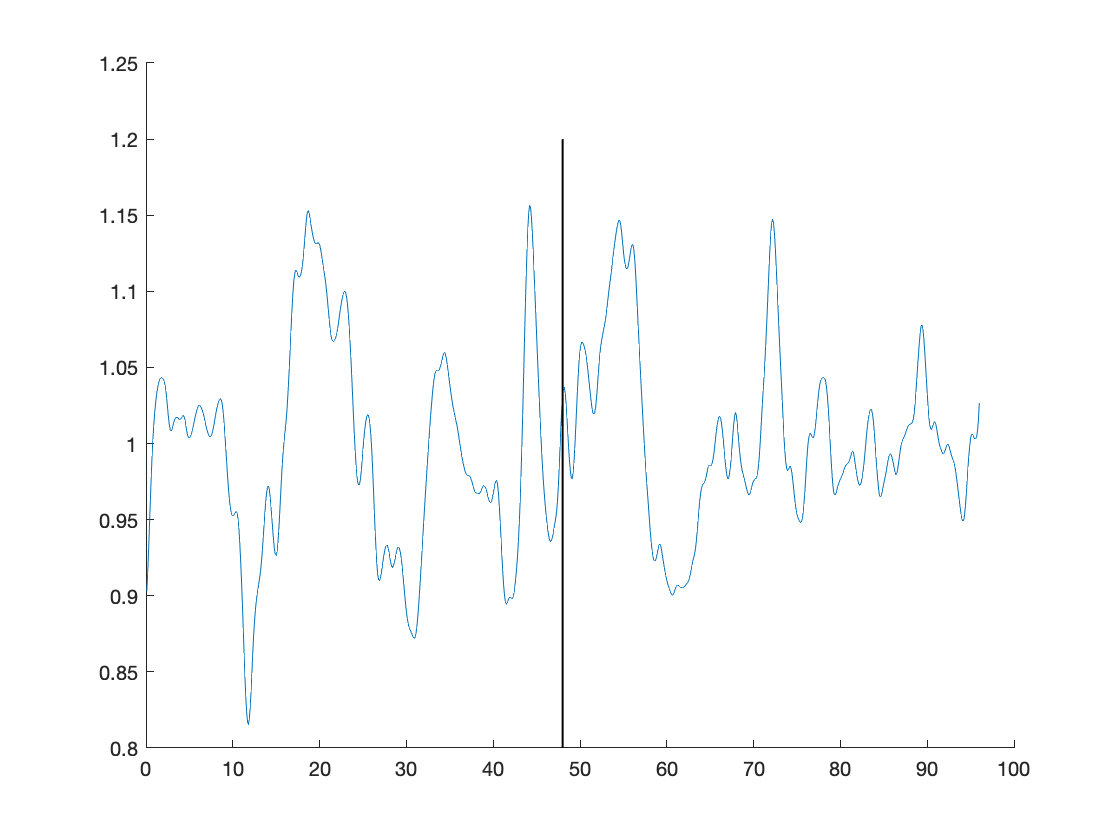

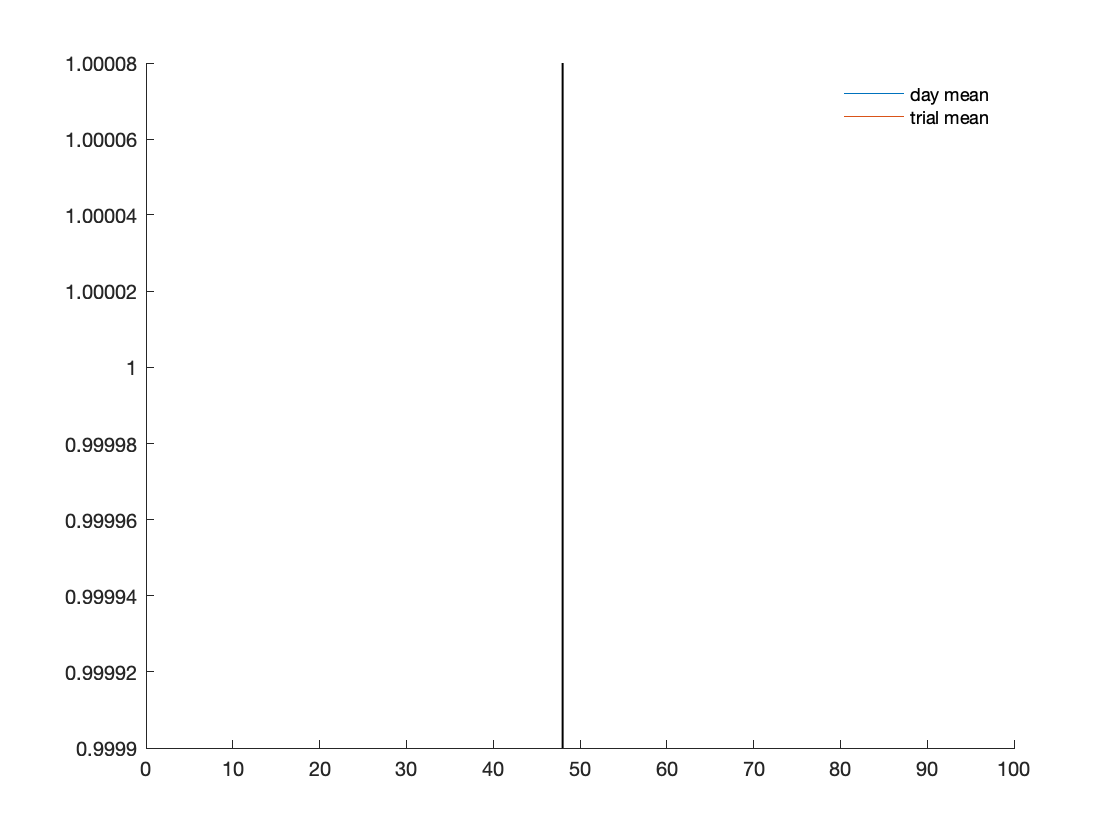

k_initialsplineplotter(kg(k));


kg(98).e(1) = kg(101).e(2);
kg(98).e(2) = kg(101).e(1);

## Fixes

for kk = 1:length(kg(k).info.luz)
    
    if kg(k).info.luz(kk) > 94 && kg(k).info.luz(kk) < 102
        kg(k).info.luz(kk) = [];
    end

end

Index exceeds the number of array elements. Index must not exceed 73.


kg(k).info.luz = [kg(k).info.luz(1:14) 98 kg(k).info.luz(15:end)];

% for kk = 1:length([kg(107).e(1).s.timcont])
% 
%     if kg(71).e(1).s(kk).timcont >= 228 & kg(71).e(1).s(kk).timcont
%     
% end


#### Gain adjustments

12:12 data

kg(116) = [kg(98).e(1).s().sumfftAmp]/20

kg(116) = [kg(98).e(2).s().sumfftAmp]/10

kg(117) = [kg(58).e(1).s().sumfftAmp]/4

kg(118) = [kg(47).e(2).s().sumfftAmp]/30

kg(119) = [kg(56).e(1).s().sumfftAmp]/4

k = 120;
channel = 2;

for kk = 1:length([kg(k).e(channel).s.sumfftAmp])

    kg(k).e(channel).s(kk).sumfftAmp = [kg(k).e(channel).s(kk).sumfftAmp]/6;

end

kg(71).info.luz = [-42.1391666666667	54.0197222222222	-58.0575000000000	62.0619444444444	-66.0302777777778	70.0255555555556	-74.0422222222222	78.0061111111111	-82.0250000000000	86.1916666666667	-90.0277777777778	94.1338888888889	-97.9955555555556	101.046111111111	-105.024166666667	109.206944444444	-113.039166666667	117.126944444444	-121.034166666667	125.022500000000	-137.020555555556	149.002777777778	-163.340000000000	168.870555555556	-180.294722222222	182.347222222222	-186.045000000000	198.005833333333	-210.040555555556	214.021388888889	-218.043611111111	222.017222222222	-226.017500000000	230.024444444444	-234.029166666667	238.008333333333	-242.051944444444	246.013611111111	-250.026666666667	254.025833333333	-258.015555555556	262.011666666667	-266.018055555556	270.474166666667	-274.015277777778	278.046944444444	-282.462500000000	294.434722222222	-306.442500000000	310.436666666667	-314.443888888889	318.464166666667	-322.458055555556	326.443888888889	-330.468055555556	334.429166666667	-338.449444444444	342.427500000000	-346.447777777778	350.440555555556	-354.466388888889	358.448611111111	-362.449444444444	366.432777777778];

# Multiple fish

## load data

load("/Volumes/Elements/kg2.mat");
%load("/Users/eric/Documents/MATLAB/kg2backup.mat");

AT HOME

load("/Users/kathryngallman/Documents/MATLAB/kg2backup.mat");
%save("/Volumes/Elements/kg2.mat", 'kg2');

## save data structure

IN LAB

save("/Users/eric/Documents/MATLAB/kg2backup.mat", "kg2");
save("/Volumes/Elements/kg2.mat", 'kg2');

AT HOME

save("/Users/kathryngallman/Documents/MATLAB/kg2backup.mat", "kg2");
save("/Volumes/Elements/kg2.mat", 'kg2');

# Multiple fish

main difference is that instead of kg.e we have kg.hifreqfish and kg.lowfreqfish 

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/Elements/Gallman/4848LD/MultiEigen48-July-19-2021-B/");
k = 15;

Calibration adjustment approx 20x for pre Jan 26 2022

12:12 LD k = 1-7

k = 1                124 - Oct-20-2021;

k = 2                12:12 LD Oct-04-2021;

k = 3                12:12 LD July-13-2021;

k = 4                12:12 with XXat end; June-29-2021;

k = 5                10:10 LD Jan-04

k = 6                12:12 LD Oct-11-2021;

k = 7                 12Ldpulse (11:1 LD) March-15-2022;

k = 8                 4:4 LD Aug-31-2021;

k = 9                10:10 LD Jan-07-2022;

k = 10               10:10 Sept-28-2921

k = 11                20:20LD    Jan-17-2022

k = 12                24:24LD Dec-05-2021

k = 13            24:24 LD Sept-3-2021 (note: sept9 data is crap - don't waste time)

k = 14            48:48 LD Dec-17-2021 (low freq fish has not dark data)

k = 16        124 (12:12 LD to 4:4 LD to 12:12LD, etc.)

k = 17        sept20 12:12 not worth it - no data

k = 20        24:24

k = 21       48:48

## generate amplitude data

calibration factor depends on when data was taken - before Feb 2022 = 20

%kg2(k).s = KseparationNoxious('Eigen*');
kg2(k).s = KatieSeparationAnxiety('Eigen*');
kg2(k).fish = KatieFishFinder(kg2(k).s, 20);

## multi plotter

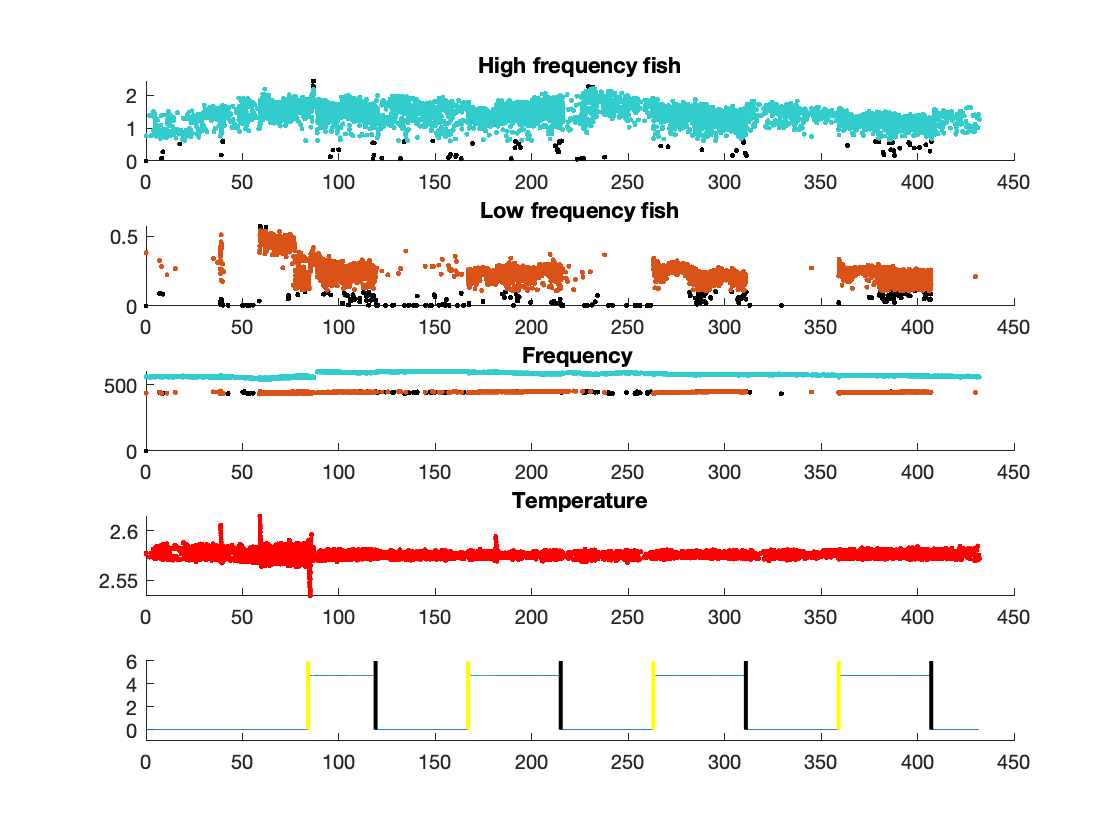

k_multiplotter(kg2(k));

#### Remove outliers

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


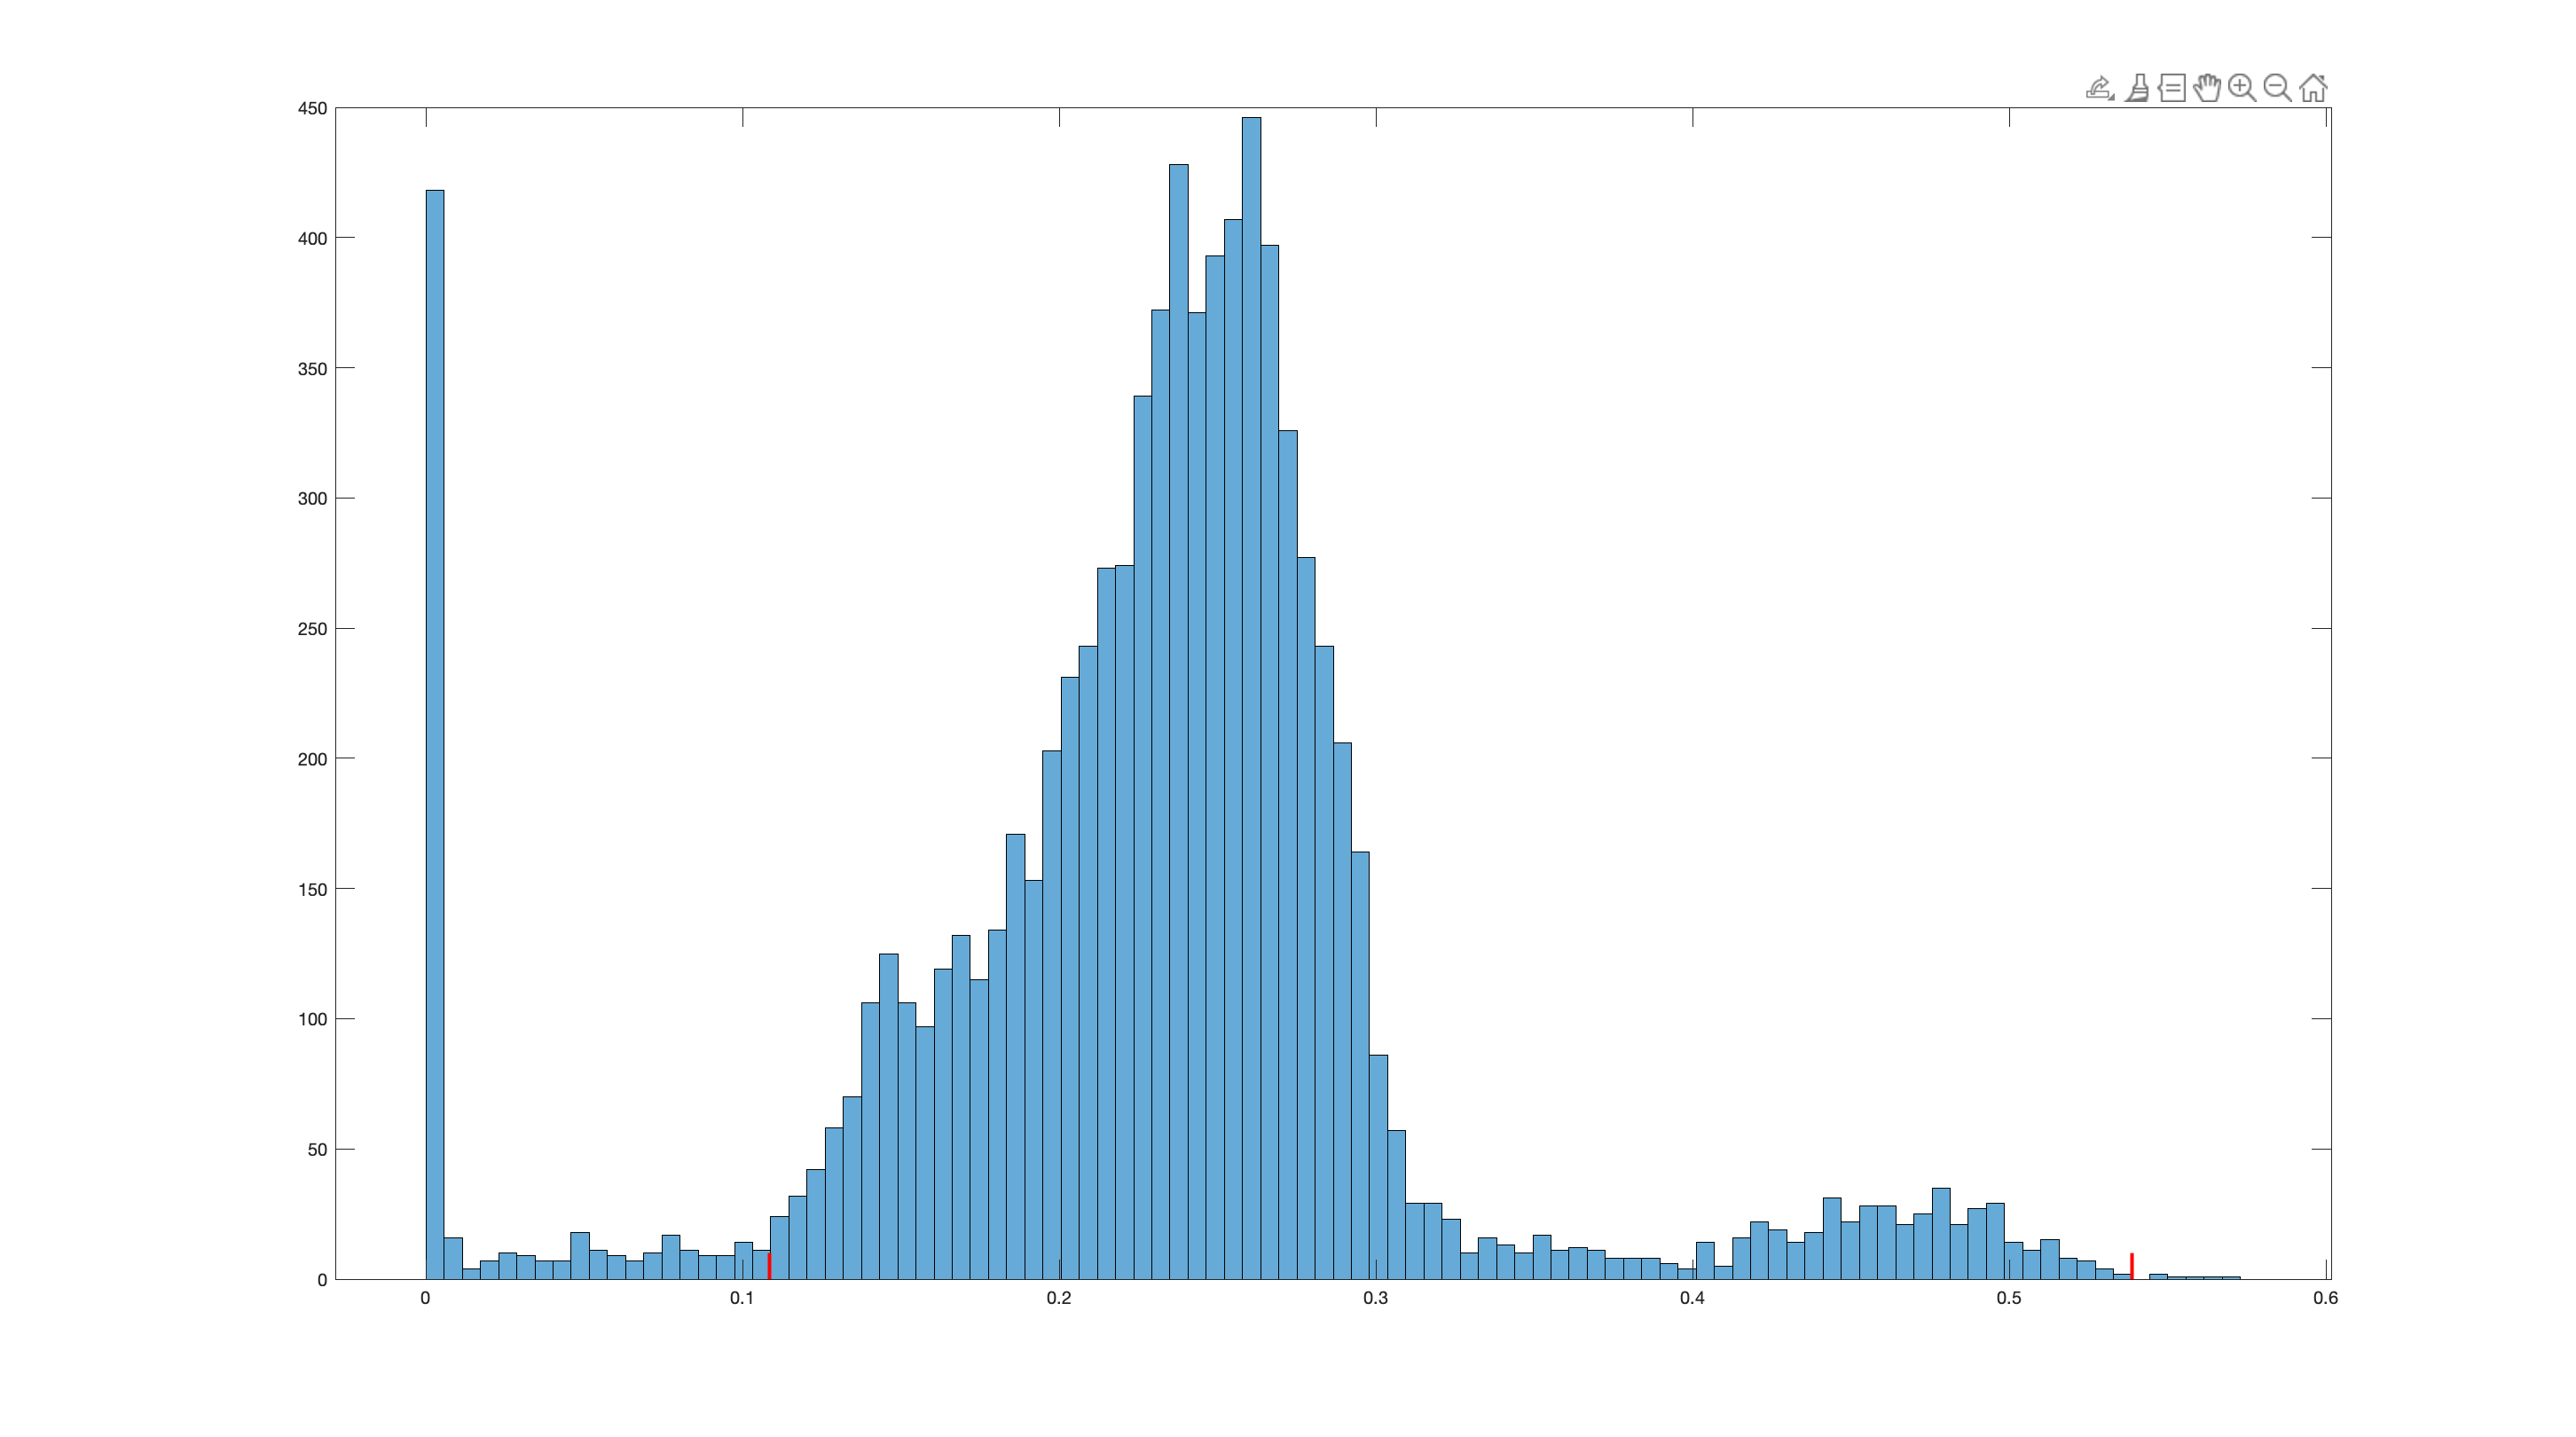

kg2(k).idx = KatieMultiRemover(kg2(k).fish);

#### Label

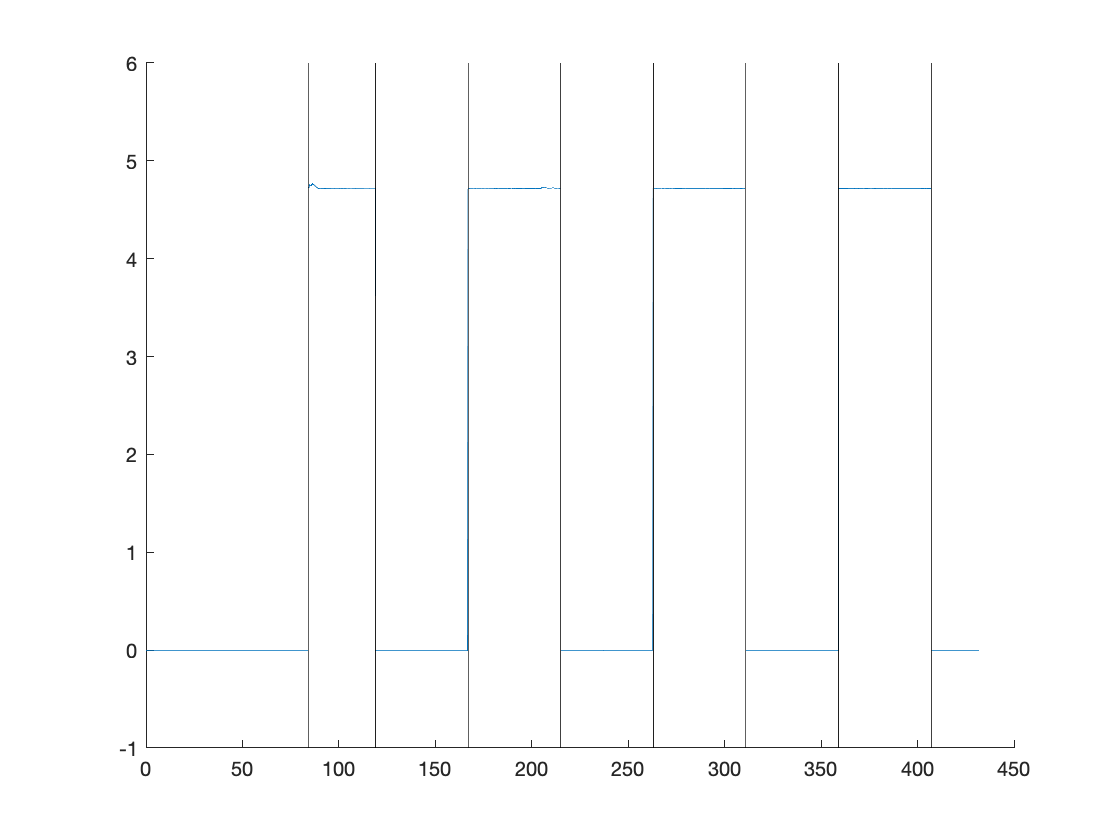

kg2(k).info = KatieMultiLabeler(kg2(k));

#### Fix

%    HiTim = [in.fish.his(tthi).HiTim];
%    HiAmp = [in.fish.his(tthi).HiAmp];
%    LoTim = [in.fish.los(ttlo).LoTim];
%    LoAmp = [in.fish.los(ttlo).LoAmp];

clear kk;
for kk = 1:length([kg2(18).fish.his.HiTim])

    kg2(18).fish.his(kk).HiTim = kg2(18).fish.his(kk).HiTim + 24;

end

clear kk;
for kk = 1:length([kg2(18).fish.los.LoTim])

    kg2(18).fish.los(kk).LoTim = kg2(18).fish.los(kk).LoTim + 24;

end






clear kk;
for kk = 1:length([kg2(18).s.timcont])

    kg2(18).s(kk).timcont = kg2(18).s(kk).timcont + (24*3600);

end



